f=fopen('C:\Users\HP\Desktop\For_Students\For Students\raster');
[pix,count]=fscanf(f,'%d',[8,14]);
pix=pix'; pix

pix =      0     0     0     0     0     0     0     1
     1     1     1     0     0     1     0     0
     1     0     0     1     0     0     0     0
     0     1     1     1     1     0     0     0
     0     0     1     0     0     1     0     0
     1     0     0     1     1     1     1     0
     0     0     0     0     0     0     0     0


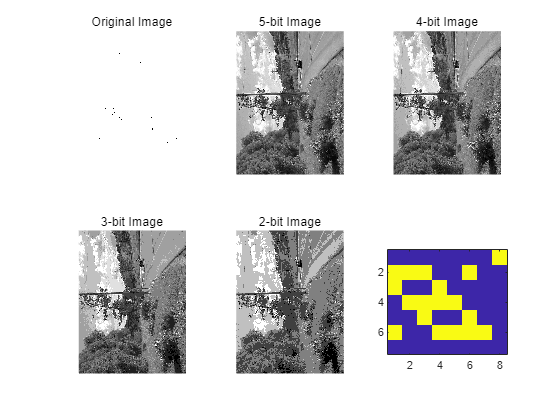

imagesc(pix)
axis('equal');
axis('image');

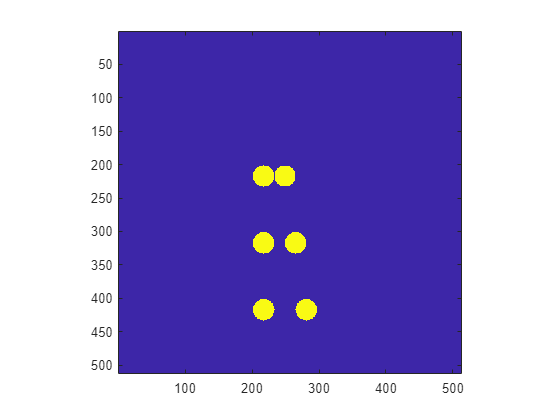

pix=zeros(512,512); 
circle=ones(33,33);
for i=1:33,
for j=1:33,
    if(sqrt((i-17)^2+(j-17)^2))> 16 circle(i,j)=0; 
        end; 
    end; 
    end;

for i=1:33,
for j=1:33,
pix(i+200,j+200)=circle(i,j); 
pix(i+232,j+200)=circle(i,j);
pix(i+200,j+300)=circle(i,j);
pix(i+248,j+300)=circle(i,j);
pix(i+200,j+400)=circle(i,j); 
pix(i+264,j+400)=circle(i,j); 
end; end;
h=imagesc(pix'); 
axis ([0 512 0 512]);
axis image;

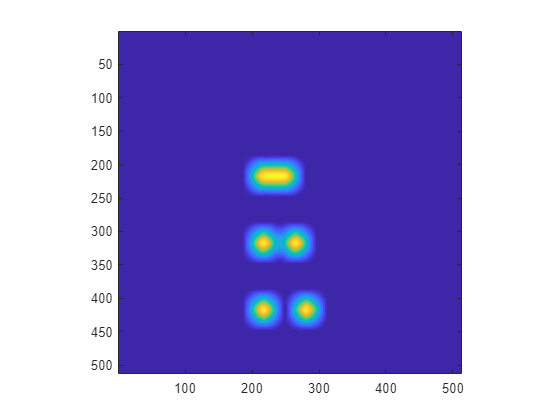

% The filtering can be done with lines like the following:  ##
filter=ones(33,33);
pix2=filter2(filter,pix,'same');
h=imagesc(pix2'); 
axis ([0 512 0 512]); 
axis image;

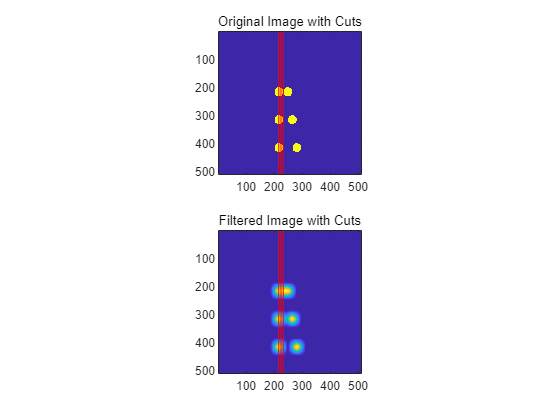


%cut line
centers = [216 200; 224 300; 232 400]; % 每对点的中心坐标
y_values = 1:512;

figure; 
subplot(2,1,1);
imagesc(pix');
hold on;
for k = 1:size(centers,1)
    plot([centers(k,1), centers(k,1)], [1, 512], 'r-'); % 绘制红色的垂直切线
end
title('Original Image with Cuts');
axis ([0 512 0 512]);
axis image;

subplot(2,1,2);
imagesc(pix2');
hold on;
for k = 1:size(centers,1)
    plot([centers(k,1), centers(k,1)], [1, 512], 'r-'); % 绘制红色的垂直切线
end
title('Filtered Image with Cuts');
axis ([0 512 0 512]);
axis image;

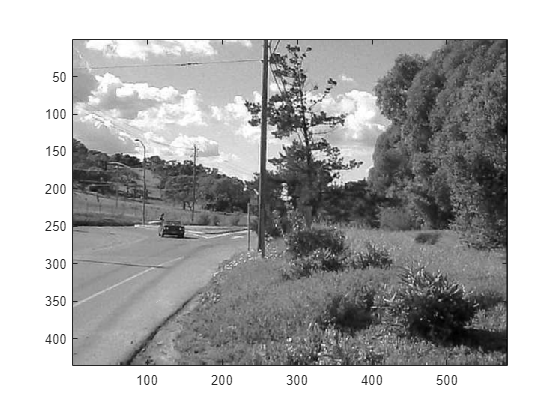

f3 = fopen('C:\Users\HP\Desktop\For_Students\For Students\campusdrive');
a = fread(f3, [580 435], 'uint8');
% f3 = fread('C:\Users\HP\Desktop\For_Students\For Students\campusdrive')
fclose(f3);
%imagesc(a);
%imshow(a, []);
filterbox1 = ones(2,2);
filterbox2 = ones(4,4);
filterbox3 = ones(8,8);
filterbox4 = ones(16,16);
a2 = filter2(filterbox1,a,'same');
a3 = imagesc(a2');
axis ([0 580 0 435]); 
axis image;

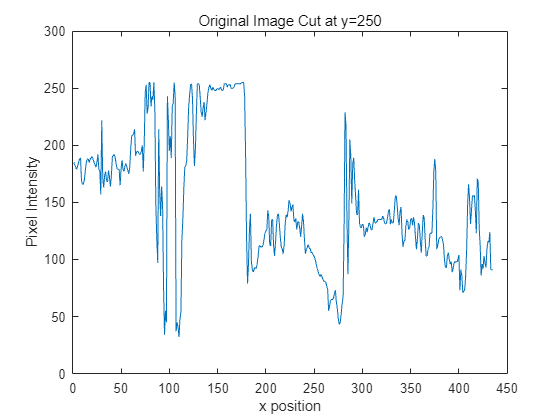


%cut line
row_to_plot = 250;

% Original Image Cut
figure;
plot(a(row_to_plot,:));
title('Original Image Cut at y=250');
xlabel('x position');
ylabel('Pixel Intensity');

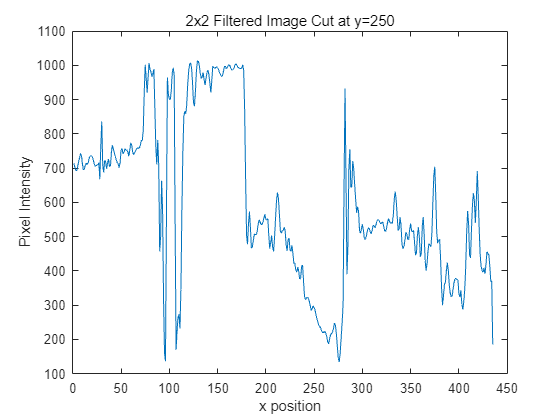


% Filtered with 2x2 box
a2 = filter2(filterbox1, a, 'same');
figure;
plot(a2(row_to_plot,:));
title('2x2 Filtered Image Cut at y=250');
xlabel('x position');
ylabel('Pixel Intensity');

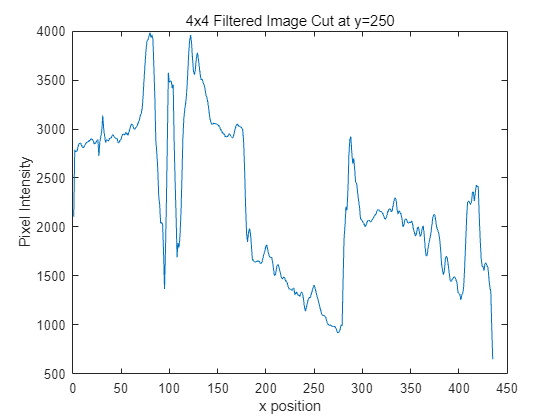


% Filtered with 4x4 box
a3 = filter2(filterbox2, a, 'same');
figure;
plot(a3(row_to_plot,:));
title('4x4 Filtered Image Cut at y=250');
xlabel('x position');
ylabel('Pixel Intensity');

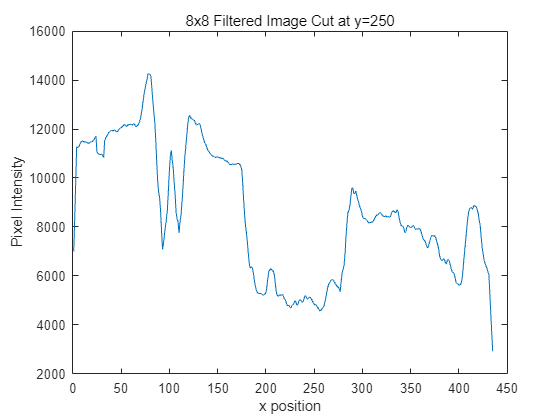


% Filtered with 8x8 box
a4 = filter2(filterbox3, a, 'same');
figure;
plot(a4(row_to_plot,:));
title('8x8 Filtered Image Cut at y=250');
xlabel('x position');
ylabel('Pixel Intensity');

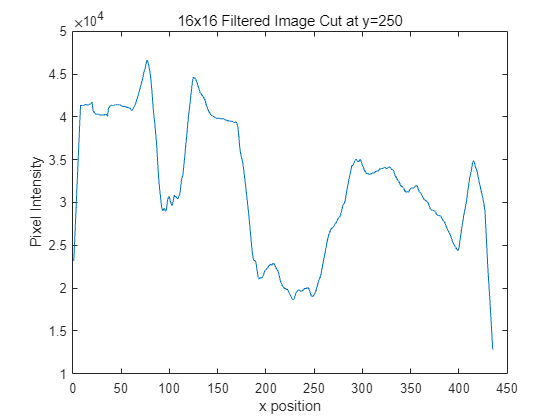


% Filtered with 16x16 box
a5 = filter2(filterbox4, a, 'same');
figure;
plot(a5(row_to_plot,:));
title('16x16 Filtered Image Cut at y=250');
xlabel('x position');
ylabel('Pixel Intensity');

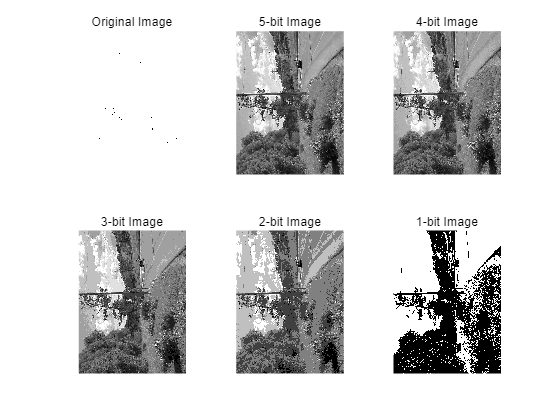

f3 = fopen('C:\Users\HP\Desktop\For_Students\For Students\campusdrive');
img = fread(f3, [580 435], 'uint8');
%量化
% 对于5位，我们需要将8位值（0-255）映射到0-31，然后再扩展到0-255
img_5bit = uint8((double(img)/256) * 32);
img_5bit = uint8((double(img_5bit)/32) * 256);

% 对于4位
img_4bit = uint8((double(img)/256) * 16);
img_4bit = uint8((double(img_4bit)/16) * 256);

% 对于3位
img_3bit = uint8((double(img)/256) * 8);
img_3bit = uint8((double(img_3bit)/8) * 256);

% 对于2位
img_2bit = uint8((double(img)/256) * 4);
img_2bit = uint8((double(img_2bit)/4) * 256);

% 对于1位
img_1bit = img > 127;  % 将图像转换为二进制
img_1bit = uint8(img_1bit * 255);  

% 3. 显示结果
figure;
subplot(2,3,1); imshow(img); title('Original Image');
subplot(2,3,2); imshow(img_5bit); title('5-bit Image');
subplot(2,3,3); imshow(img_4bit); title('4-bit Image');
subplot(2,3,4); imshow(img_3bit); title('3-bit Image');
subplot(2,3,5); imshow(img_2bit); title('2-bit Image');
subplot(2,3,6); imshow(img_1bit); title('1-bit Image');

nofile = fopen('C:\Users\HP\Desktop\For_Students\For Students\lab3prob5data')

nofile = 82

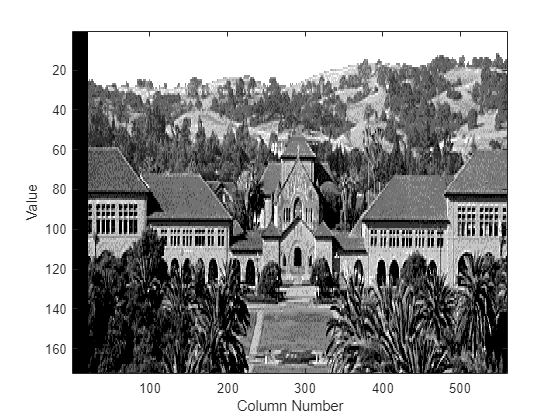


xlabel('Column Number');
ylabel('Value');


nonfile = fread(nofile,[1 inf],"uint8")

nonfile =      0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255


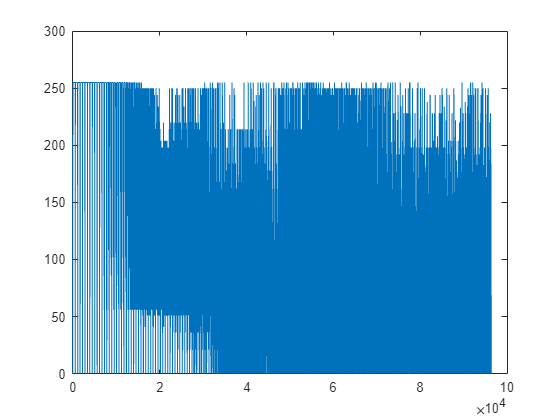

for i = 1:size(nonfile, 1)
    plot(nonfile(i, :));
    %hold on;
end




nonfile = fread(nofile,[560 inf],"uint8")


nonfile =

     []



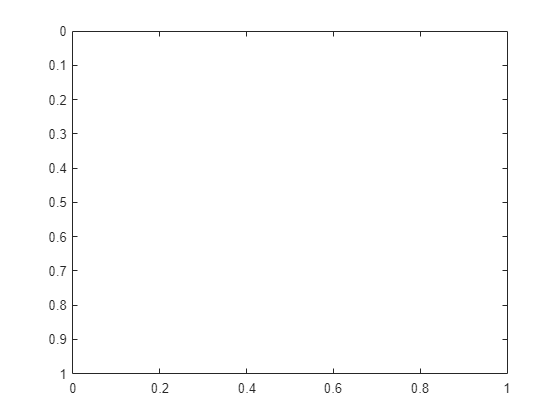

figure;
colormap('gray') ;
imagesc(nonfile');

nonfile(1:20, :) = repmat(nonfile(1, :), 20, 1)

位置 1 处的索引超出数组边界。

imagesc(nonfile');

%plot(nonfile)

% nonfile(1:21, :) = repmat(nonfile(21, :), 21, 1);
% figure;
% colormap('gray') ;
% imagesc(nonfile');
% 
% [row, col] = size(nonfile)
% figure;

% 确定每一行的实际数据字节 header 20*173
% actual_data_bytes_per_line = zeros(1, row);
% for i = 1:row
%     actual_data_bytes_per_line(i) = sum(nonfile(i,:) == 255);
% end
% header_size = sum(sum(nonfile ~= 255))
% sum_actural = 0;
% for j = 1 :312
%     sum_actural = sum_actural + sum(actual_data_bytes_per_line(j))
% end
% sum_actural
